## Markov Model for Sleep State Transitions

% File load and read in filters
clear all
close all

warning("off", 'all') % Turns off annoying warnings about table alterations that MATLAB does when it imports from excel
TypeStrain = "DBA"

TypeStrain = "DBA"

TypeDay    = "3"

TypeDay = "3"

TypeInj    = "SA"

TypeInj = "SA"

outputdir = cd("P:\Jones_Maganti_Shared\Sleep Dep\Markov Output Figures\DBA\DBA SA Day 3\"); % Set output file path



% This section creates various arrays that will be used later on
ExcelArr   = readtable("Master Sheet Sleep Dep.xlsx");
filename   = "Master Sheet Sleep Dep.xlsx";            
opts       = detectImportOptions(filename);
opts       = setvartype(opts, 'string');
ExcelArr_Str = readtable(filename, opts);   

% Creates variables to select for the desired groupings specified above
Strain      = contains(ExcelArr.Strain, TypeStrain);
Day        = contains(ExcelArr_Str.Day, TypeDay);
Good_Files = contains(ExcelArr.DataQuality, "Good");
Injection  = contains(ExcelArr.Injections, TypeInj);

ExcelRows  = 2:height(ExcelArr)+1;                                   
MatlabRows = ExcelRows - 1;                                       % Row indexing correction between excel and MATLAB tables
MatlabRows = MatlabRows(Good_Files & Strain & Day & Injection);   % Read in good files conforming to the above criteria
FileArr    = ExcelArr(MatlabRows, 'FilePath');
FileArr    = table2array(FileArr);
FileArr    = string(FileArr);
fileNameTXT = strcat(FileArr,'.txt');


chunks = 1

lower = 1

lower = 1

lower = 1

lower = 1

lower = 1

P =     6.7187    0.0381         0
    0.0353    1.4552    0.0019
    0.0019         0    0.0402


c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [0 0.1000]
    FontSize: 8.1000
    Position: [0.6631 0.5875 0.0286 0.3375]
       Units: 'normalized'

  Show all properties


ht =   HeatmapChart with properties:

        XData: {3×1 cell}
        YData: {3×1 cell}
    ColorData: [3×3 double]

  Show all properties


chunks = 2

P =     5.9612    0.1622         0
    0.1594    1.9513         0
         0         0         0


P =     5.9612    0.1622         0
    0.1594    1.9513         0


P =     5.9612    0.1622
    0.1594    1.9513


mc =   dtmc with properties:

             P: [2×2 double]
    StateNames: ["LWake"    "NREM"]
     NumStates: 2


c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [0 0.1000]
    FontSize: 8.1000
    Position: [0.6631 0.5875 0.0286 0.3375]
       Units: 'normalized'

  Show all properties


heatmap_arr =     0.9735    0.0265       NaN
    0.0755    0.9245       NaN
       NaN       NaN       NaN


ht =   HeatmapChart with properties:

        XData: {3×1 cell}
        YData: {3×1 cell}
    ColorData: [3×3 double]

  Show all properties


chunks = 3

P =     2.4938    0.0549         0
    0.0251    5.1310    0.0204
    0.0186    0.0019    0.5259


c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [0 0.1000]
    FontSize: 8.1000
    Position: [0.6631 0.5875 0.0286 0.3375]
       Units: 'normalized'

  Show all properties


ht =   HeatmapChart with properties:

        XData: {3×1 cell}
        YData: {3×1 cell}
    ColorData: [3×3 double]

  Show all properties


chunks = 4

P =     1.5227    0.0455         0
    0.0242    6.2037    0.0223
    0.0223         0    0.5103


c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [0 0.1000]
    FontSize: 8.1000
    Position: [0.6631 0.5875 0.0286 0.3375]
       Units: 'normalized'

  Show all properties


ht =   HeatmapChart with properties:

        XData: {3×1 cell}
        YData: {3×1 cell}
    ColorData: [3×3 double]

  Show all properties


chunks = 5

P =     2.2047    0.0390         0
    0.0204    5.5227    0.0195
    0.0186         0    0.5224


c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [0 0.1000]
    FontSize: 8.1000
    Position: [0.6631 0.5875 0.0286 0.3375]
       Units: 'normalized'

  Show all properties


ht =   HeatmapChart with properties:

        XData: {3×1 cell}
        YData: {3×1 cell}
    ColorData: [3×3 double]

  Show all properties


chunks = 6

P =     5.1247    0.0316         0
    0.0250    2.9165    0.0093
    0.0102         0    0.2337


c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [0 0.1000]
    FontSize: 8.1000
    Position: [0.6631 0.5875 0.0286 0.3375]
       Units: 'normalized'

  Show all properties


ht =   HeatmapChart with properties:

        XData: {3×1 cell}
        YData: {3×1 cell}
    ColorData: [3×3 double]

  Show all properties


chunks = 7

P =     5.4519    0.0213         0
    0.0130    2.7184    0.0074
    0.0065    0.0009    0.1316


c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [0 0.1000]
    FontSize: 8.1000
    Position: [0.6631 0.5875 0.0286 0.3375]
       Units: 'normalized'

  Show all properties


ht =   HeatmapChart with properties:

        XData: {3×1 cell}
        YData: {3×1 cell}
    ColorData: [3×3 double]

  Show all properties


chunks = 8

P =     5.0977    0.0260         0
    0.0167    3.0716    0.0093
    0.0093         0    0.1205


c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [0 0.1000]
    FontSize: 8.1000
    Position: [0.6631 0.5875 0.0286 0.3375]
       Units: 'normalized'

  Show all properties


ht =   HeatmapChart with properties:

        XData: {3×1 cell}
        YData: {3×1 cell}
    ColorData: [3×3 double]

  Show all properties


chunks = 9

P =     5.7328    0.0214         0
    0.0149    2.4622    0.0065
    0.0065         0    0.0984


c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [0 0.1000]
    FontSize: 8.1000
    Position: [0.6631 0.5875 0.0286 0.3375]
       Units: 'normalized'

  Show all properties


ht =   HeatmapChart with properties:

        XData: {3×1 cell}
        YData: {3×1 cell}
    ColorData: [3×3 double]

  Show all properties


chunks = 10

P =     4.3055    0.0371         0
    0.0232    3.6322    0.0139
    0.0139         0    0.3253


c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [0 0.1000]
    FontSize: 8.1000
    Position: [0.6631 0.5875 0.0286 0.3375]
       Units: 'normalized'

  Show all properties


ht =   HeatmapChart with properties:

        XData: {3×1 cell}
        YData: {3×1 cell}
    ColorData: [3×3 double]

  Show all properties


chunks = 11

lower = 19800

upper = 21596

lower = 19800

upper = 21596

lower = 19800

upper = 21596

lower = 19800

upper = 21596

lower = 19800

upper = 21596

P =     3.5355    0.0353         0
    0.0204    4.4341    0.0111
    0.0111         0    0.2867


c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [0 0.1000]
    FontSize: 8.1000
    Position: [0.6631 0.5875 0.0286 0.3375]
       Units: 'normalized'

  Show all properties


ht =   HeatmapChart (Transition Matrix Heatmap for DBA SA-3 (%)) with properties:

        XData: {3×1 cell}
        YData: {3×1 cell}
    ColorData: [3×3 double]

  Show all properties


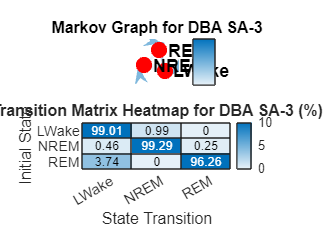



%% Empirical Transition Proportion Caclulation

C_Ratios = cell(1, length(MatlabRows));    % Allocate appropriate length cell array

for chunks = 1:11
    chunks
for x = 1:length(MatlabRows)
    data        = readtable(fileNameTXT(x));
    current_file = (FileArr(x));



Sleep_State = data.Score_;

% Initialize variables to begin counting, they need to be initialized outside of the for loop

Wake2Wake = 0;        
Wake2NREM = 0;
Wake2REM  = 0;
NREM2Wake = 0;
NREM2NREM = 0;
NREM2REM  = 0;
REM2Wake  = 0;
REM2NREM  = 0;
REM2REM   = 0;




% This section iterates through each .txt file in two hour chunks. 900 data
% points per hour. the first and last hours were cut off of the txt files,
% so there will only be 11x2hr chunks.

if chunks == 1
    lower = 1
else
    lower = (1800 * (chunks - 1)) + 1;
end 

upper = 1800 * chunks;

if chunks == 11
    lower = (1800 * chunks - 1) + 1  
    upper = height(data) - 1
end

% This for loop tallies each instance of a particular transition. In other
% words, an empirical count for all types of transitions. It iterates
% through each point and compares the next point to the current point to
% categorize a transition as described in the txt file scoring.

% 1 = Wake
% 2 = NREM
% 3 = REM

% Given the possibilites, there are 9 total transition types

for z = lower:upper            
    S1 = Sleep_State(z);                 
    S2 = Sleep_State(z + 1);
    if S1 == 1 && S2 == 1
        Wake2Wake = Wake2Wake + 1; 
    end

    if S1 == 1 && S2 == 2
        Wake2NREM = Wake2NREM + 1;
    end

    if S1 == 1 && S2 == 3
        Wake2REM = Wake2REM + 1;
    end

    if S1 == 2 && S2 == 1
        NREM2Wake = NREM2Wake + 1;
    end

    if S1 == 2 && S2 == 2
        NREM2NREM = NREM2NREM + 1;
    end

    if S1 == 2 && S2 == 3
        NREM2REM = NREM2REM + 1;
    end

    if S1 == 3 && S2 == 1
        REM2Wake = REM2Wake + 1;
    end

    if S1 == 3 && S2 == 2
        REM2NREM = REM2NREM + 1;
    end

    if S1 == 3 && S2 == 3
        REM2REM = REM2REM + 1;
    end

end

Ratios = [Wake2Wake, Wake2NREM, Wake2REM, NREM2Wake, NREM2NREM, NREM2REM, REM2Wake, ... 
    REM2NREM, REM2REM]' ./ ((height(data)-1) - length(Sleep_State(Sleep_State == 0))); 

C_Ratios{1, x} = Ratios;
end

C_Ratios;
Avg_C_Ratios = mean(cell2mat(C_Ratios), 2);


%% Figures


P = reshape(Avg_C_Ratios, [3, 3])';
P = 100*P


% 1: all states encountered (default)

if sum(P(1, :)) > 0 && sum(P(2, :)) > 0 && sum(P(3, :)) > 0
   mc = dtmc(P, "StateNames", ["LWake", "NREM", "REM"]); 
   imagesc(mc.P)
   colormap(jet)

tiledlayout(2, 1)
nexttile
    gr = graphplot(mc, 'ColorEdges',true);
    axis square
    axis off
    colormap sky
    gr.LineWidth = 1.7;
    gr.LineStyle = "-";
    gr.NodeFontSize = 10;
    title('Markov Graph for ' + TypeStrain + " " + TypeInj + "-" + TypeDay);
    clim([0 0.1])
    c = colorbar('Ticks', [])

nexttile
    
    xvalues = {"LWake", "NREM", "REM"};
    yvalues = {"LWake", "NREM", "REM"};
    graph_prep_arr = reshape(Avg_C_Ratios * 100, [3, 3])';
    ht = heatmap(xvalues, yvalues, round(mc.P*100, 2))
    colormap sky
    ht.Title  = "Transition Matrix Heatmap for " + TypeStrain + " " + TypeInj + "-" + TypeDay + " (%)";
    ht.XLabel = "State Transition";
    ht.YLabel = "Initial State";
    clim([0, 10])
saveas(gcf, "2Hr Markov Output for " + TypeStrain + " " + TypeInj + "-" + TypeDay + " Chunk " + chunks, 'png')


% 2: Wake and NREM not encountered (all Wake and NREM set to NaN, output
% single value of 1.00 for REM to REM) this type of situation is highly
% unlikely, if you encounter it, something is probably wrong with the code.
% the likelihood of multiple mice being in one state for two hours is
% extremely small. This same logic follows for all situations where only
% one state is encountered

elseif sum(P(1, :)) == 0 && sum(P(2, :)) == 0
    P = P(3, 3)
    mc = dtmc(P, "StateNames", "REM")
    imagesc(mc.P)
    colormap(jet)

tiledlayout(2, 1)
nexttile
    gr = graphplot(mc, 'ColorEdges',true);
    axis square
    axis off
    colormap sky
    gr.LineWidth = 1.7;
    gr.LineStyle = "-";
    gr.NodeFontSize = 10;
    title('Markov Graph for ' + TypeStrain + " " + TypeInj + "-" + TypeDay);
    clim([0 0.1])
    c = colorbar('Ticks', [])
nexttile
    heatmap_arr = [NaN, NaN, NaN;
                   NaN, NaN, NaN;
                   0,    0,    1]
    xvalues = {"LWake", "NREM", "REM"};
    yvalues = {"LWake", "NREM", "REM"};
    ht = heatmap(xvalues, yvalues, 100 * heatmap_arr)
    colormap sky
    ht.Title  = "Transition Matrix Heatmap for " + TypeStrain + " " + TypeInj + "-" + TypeDay + " (%)";
    ht.XLabel = "State Transition";
    ht.YLabel = "Initial State";
    clim([0, 10])
    saveas(gcf, "2Hr Markov Output for " + TypeStrain + " " + TypeInj + "-" + TypeDay + " Chunk " + chunks, 'png')

% 3: Wake and REM not encountered (NREM to NREM only encountered)

elseif sum(P(1, :)) == 0 && sum(P(3, :)) == 0
    P = P(2, 2)
    mc = dtmc(P, "StateNames", "NREM")
    imagesc(mc.P)
    colormap(jet)
tiledlayout(2, 1)
nexttile
    gr = graphplot(mc, 'ColorEdges',true);
    axis square
    axis off
    colormap sky
    gr.LineWidth = 1.7;
    gr.LineStyle = "-";
    gr.NodeFontSize = 10;
    title('Markov Graph for ' + TypeStrain + " " + TypeInj + "-" + TypeDay);
    clim([0 0.1])
    c = colorbar('Ticks', [])
nexttile
    heatmap_arr = [NaN, NaN, NaN;
                   0,    1,    0;
                   NaN, NaN, NaN]
    xvalues = {"LWake", "NREM", "REM"};
    yvalues = {"LWake", "NREM", "REM"};
    ht = heatmap(xvalues, yvalues, 100 * heatmap_arr)
    colormap sky
    ht.Title  = "Transition Matrix Heatmap for " + TypeStrain + " " + TypeInj + "-" + TypeDay + " (%)";
    ht.XLabel = "State Transition";
    ht.YLabel = "Initial State";
    clim([0, 10])
    saveas(gcf, "2Hr Markov Output for " + TypeStrain + " " + TypeInj + "-" + TypeDay + " Chunk " + chunks, 'png')


% 4: REM and NREM not encountered (Wake to Wake only)
elseif sum(P(2, :)) == 0 && sum(P(3, :)) == 0
    P = P(1, 1)
    mc = dtmc(P, "StateNames", "LWake")
    imagesc(mc.P)
    colormap(jet)
tiledlayout(2, 1)
nexttile
    gr = graphplot(mc, 'ColorEdges',true);
    axis square
    axis off
    colormap sky
    gr.LineWidth = 1.7;
    gr.LineStyle = "-";
    gr.NodeFontSize = 10;
    title('Markov Graph for ' + TypeStrain + " " + TypeInj + "-" + TypeDay);
    clim([0 0.1])
    c = colorbar('Ticks', [])
nexttile
    heatmap_arr = [0,    1,    0;
                   NaN, NaN, NaN;
                   NaN, NaN, NaN]
    xvalues = {"LWake", "NREM", "REM"};
    yvalues = {"LWake", "NREM", "REM"};
    ht = heatmap(xvalues, yvalues, 100 * heatmap_arr)
    colormap sky
    ht.Title  = "Transition Matrix Heatmap for " + TypeStrain + " " + TypeInj + "-" + TypeDay + " (%)";
    ht.XLabel = "State Transition";
    ht.YLabel = "Initial State";
    clim([0, 10])
    saveas(gcf, "2Hr Markov Output for " + TypeStrain + " " + TypeInj + "-" + TypeDay + " Chunk " + chunks, 'png')

% 5: Wake not encountered

elseif sum(P(1, :)) == 0
    P(1, :)    = []
    P(:, 1) = []     % Remove unencountered section, result should be 2x2 matrix of NREM and REM
    mc = dtmc(P, "StateNames", ["NREM", "REM"])
    imagesc(mc.P)
    colormap(jet)
tiledlayout(2, 1)
nexttile
    gr = graphplot(mc, 'ColorEdges',true);
    axis square
    axis off
    colormap sky
    gr.LineWidth = 1.7;
    gr.LineStyle = "-";
    gr.NodeFontSize = 10;
    title('Markov Graph for ' + TypeStrain + " " + TypeInj + "-" + TypeDay);
    clim([0 0.1])
    c = colorbar('Ticks', [])
nexttile
    heatmap_arr = [NaN,        NaN,        NaN;
                   NaN, mc.P(1, 1), mc.P(1, 2);
                   NaN, mc.P(2, 1), mc.P(2, 2)]
    xvalues = {"LWake", "NREM", "REM"};
    yvalues = {"LWake", "NREM", "REM"};
    ht = heatmap(xvalues, yvalues, 100 * heatmap_arr)
    colormap sky
    ht.Title  = "Transition Matrix Heatmap for " + TypeStrain + " " + TypeInj + "-" + TypeDay + " (%)";
    ht.XLabel = "State Transition";
    ht.YLabel = "Initial State";
    clim([0, 10])
    saveas(gcf, "2Hr Markov Output for " + TypeStrain + " " + TypeInj + "-" + TypeDay + " Chunk " + chunks, 'png')


% 6: NREM not encountered
elseif sum(P(2, :)) == 0
    P(2, :) = []
    P(:, 2) = []
    mc = dtmc(P, "StateNames", ["LWake", "REM"])
    imagesc(mc.P)
    colormap(jet)
tiledlayout(2, 1)
nexttile
    gr = graphplot(mc, 'ColorEdges',true);
    axis square
    axis off
    colormap sky
    gr.LineWidth = 1.7;
    gr.LineStyle = "-";
    gr.NodeFontSize = 10;
    title('Markov Graph for ' + TypeStrain + " " + TypeInj + "-" + TypeDay);
    clim([0 0.1])
    c = colorbar('Ticks', [])
nexttile
    heatmap_arr = [mc.P(1, 1), NaN, mc.P(1, 2);
                   NaN,        NaN,        NaN;
                   mc.P(2, 1), NaN. mc.P(2, 2)]
    xvalues = {"LWake", "NREM", "REM"};
    yvalues = {"LWake", "NREM", "REM"};
    ht = heatmap(xvalues, yvalues, 100 * heatmap_arr)
    colormap sky
    ht.Title  = "Transition Matrix Heatmap for " + TypeStrain + " " + TypeInj + "-" + TypeDay + " (%)";
    ht.XLabel = "State Transition";
    ht.YLabel = "Initial State";
    clim([0, 10])
    saveas(gcf, "2Hr Markov Output for " + TypeStrain + " " + TypeInj + "-" + TypeDay + " Chunk " + chunks, 'png')

% 7: REM not encountered
elseif sum(P(3, :)) == 0
       P(3, :) = []
       P(:, 3) = []
    mc = dtmc(P, "StateNames", ["LWake", "NREM"])
    imagesc(mc.P)
    colormap(jet)
tiledlayout(2, 1)
nexttile
    gr = graphplot(mc, 'ColorEdges',true);
    axis square
    axis off
    colormap sky
    gr.LineWidth = 1.7;
    gr.LineStyle = "-";
    gr.NodeFontSize = 10;
    title('Markov Graph for ' + TypeStrain + " " + TypeInj + "-" + TypeDay);
    clim([0 0.1])
    c = colorbar('Ticks', [])
nexttile
    heatmap_arr = [mc.P(1, 1), mc.P(1, 2), NaN;
                   mc.P(2, 1), mc.P(2, 2), NaN;
                   NaN,        NaN,        NaN]
    xvalues = {"LWake", "NREM", "REM"};
    yvalues = {"LWake", "NREM", "REM"};
    ht = heatmap(xvalues, yvalues, 100 * heatmap_arr)
    colormap sky
    ht.Title  = "Transition Matrix Heatmap for " + TypeStrain + " " + TypeInj + "-" + TypeDay + " (%)";
    ht.XLabel = "State Transition";
    ht.YLabel = "Initial State";
    clim([0, 10])
    saveas(gcf, "2Hr Markov Output for " + TypeStrain + " " + TypeInj + "-" + TypeDay + " Chunk " + chunks, 'png')
end

end    %--------- Chunk Loop End --------%             